# Performance evaluation: ROC curves

You are working on a project to classify between cancerous (malignant) and healthy (benign) biopsies. Your colleague has shared two trained classifiers with you and some previously unseen testing data:

clear all;
load('classifiers.mat', 'm_nb', 'm_dt', 'test_examples', 'test_labels');

Your task is to analyse the True Positive Rate (TPR) and False Positive Rate (FPR) for each classifier in order to make a decision about which one is performing best.

Marks are available for:

- Using each classifier to predict labels and associated likelihood scores for the test data [4 marks]

- Computing the TPR for each classifier, taking "malignant" as the positive class [3 marks]

- Computing the FPR for each classifier, taking "malignant" as the positive class [3 marks]

- Generating a Receiver Operating Characteristic (ROC) curve for each classifier and plotting them together on a single graph with a legend and labelled axes [4 marks]

- Deciding on the best classifier based on a sensible quantitative comparison between the ROC curves [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% Question 1
% make predictions and store associated likelihood scores for each trained classifier:
[nb_predictions, nb_scores] = predict(m_nb, test_examples);
[dt_predictions, dt_scores] = predict(m_dt, test_examples);

% output a confusion matrix for naive bayes classifier:
[nb_c, ~] = confusionmat(test_labels, nb_predictions)

nb_c =     83     2
     4    53



% output a confusions matrix for decision trees classifier:
[dt_c, order] = confusionmat(test_labels, dt_predictions)

dt_c =     82     3
     5    52


order = 2×1 categorical array
     Benign 
     Malignant 



% calculate TPR scores for nb and dt taking malignant as positive:
nb_TPR = nb_c(2,2) / sum(nb_c(2,:))

nb_TPR = 0.9298

dt_TPR = dt_c(2,2) / sum(dt_c(2,:))

dt_TPR = 0.9123


% calculate FPR scores for nb and dt taking malignant as positive:
nb_FPR = nb_c(1,2) / sum(nb_c(1,:))

nb_FPR = 0.0235

dt_FPR = dt_c(1,2) / sum(dt_c(1,:))

dt_FPR = 0.0353

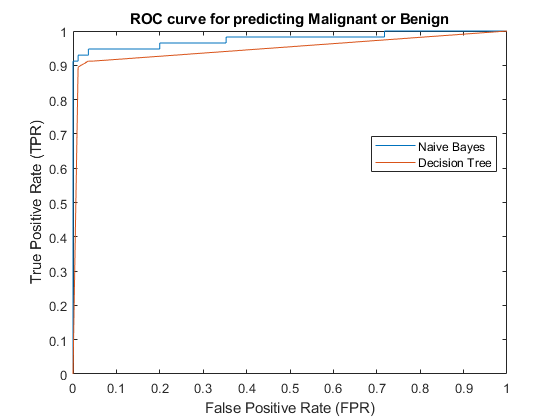


% create an ROC curve for the nb classifier:
[nb_x,nb_y] = perfcurve(test_labels, nb_scores(:,2), 'Malignant');
plot(nb_x,nb_y)
hold on
% create an ROC curve for the dt classifier:
[dt_x,dt_y] = perfcurve(test_labels, dt_scores(:,2), 'Malignant');
plot(dt_x,dt_y)

% set axis's, title, and legend:
xlabel('False Positive Rate (FPR)')
ylabel('True Positive Rate (TPR)')
title('ROC curve for predicting Malignant or Benign')
legend('Naive Bayes','Decision Tree','Location','best')
hold off


% looking at the ROC curve graph, it shows that the best classifier
% for predicting Malignant or Benign is the Naive Bayes classifer.
% This is becuase it has the greatest area under the graph, and 
% therefore is the best at classifying positive examples.